Il codice ottiene i punti e le orientazioni da tre file nel formato 

x y z phi theta psi

Poi crea la matrice di rototraslazione per ogni punto e disegna la traiettoria

In particolare, il primo file serve per l'avvicinamento al cono, il secondo file per servire il cono al cliente, il terzo file per tornare alla posizione iniziale.


close all
clc
clear

OURrobot = importrobot("Doosan_Scatola_Girata.urdf");
% sistema i vincoli
% assicura che i vincoli siano corretti secondo il datasheet
for i = 1:10
    if strcmp(OURrobot.Bodies{1,i}.Joint.Type, 'revolute')
        OURrobot.Bodies{1,i}.Joint.PositionLimits = [-2*pi 2*pi];
    end
end
OURrobot.Bodies{1,6}.Joint.PositionLimits = [-15/18*pi 15/18*pi];
OURrobot.Bodies{1,3}.Joint.PositionLimits = [-pi/2 pi/2];
OURrobot.DataFormat = 'row';


La cinematica inversa viene calcolata usando la funzione gik del Robotics Toolbox di Matlab.

I parametri della funzione vengono modificati per fornire una soluzione più precisa.

gik = generalizedInverseKinematics("RigidBodyTree", OURrobot, "ConstraintInputs", {'joint', 'pose'});
gik.SolverParameters.MaxIterations = 5000;
gik.SolverParameters.GradientTolerance = 1e-8;
gik.SolverParameters.SolutionTolerance = 1e-8;
gik.SolverParameters.AllowRandomRestart = false;
        
jointLim = constraintJointBounds(OURrobot);

% sistema vicoli per tutti i giunti
jointLim.Bounds(:, 1) = -2*pi * ones(1,6);
jointLim.Bounds(:, 2) = 2*pi * ones(1,6);

% imposta vincoli per il terzo giunto secondo il datasheet
% jointLim.Bounds è una matrice 5x2
jointLim.Bounds(3, 1) = -0.83*pi;
jointLim.Bounds(3, 2) = 0.83*pi;

% imposta i vincoli per il secondo giunto, non deve andare a zeta negative
jointLim.Bounds(2, 1) = -pi/2;
jointLim.Bounds(2, 2) = pi/2;

% imposta la posa
poseConst = constraintPoseTarget("MODULE.1_FLANGE-END");

% per ogni punto poi la gik viene chiamata come:
% poseConst.TargetTransform = T0ee;
% q = gik(guess, jointLim, poseConst);

% test per capire se i limiti danno problemi
% gik.SolverParameters.EnforceJointLimits = false;

%% aggiunge end effector
file_ee = "end_effector.stl";
ee = stlread(file_ee);

socket_ee = rigidBody("end_effector");
jntee = rigidBodyJoint('jntee', 'fixed');

% calcola la trasformata del cono rispetto alla base
p = [0 0 -0.05];
phi = pi/2; theta = pi/2; psi = pi/2;
R = eul2r(phi, theta, psi);
T = rot_transl(R, p);
setFixedTransform(jntee, T);
socket_ee.Joint = jntee;

addVisual(socket_ee, "Mesh", file_ee);

addBody(OURrobot, socket_ee, 'MODULE.1_FLANGE-END');


## Aggiunta del cono al robot

Nella posizione iniziale


file_cono = "cono_gelato.stl";
cono = stlread(file_cono);

socket = rigidBody("cono_gelato");
jntcono = rigidBodyJoint('jntcono', 'fixed');

% calcola la trasformata del cono rispetto alla base
p = [-0.5 -0.6 0.4];
T = rot_transl(eye(3), p);
setFixedTransform(jntcono, T);
socket.Joint = jntcono;

addVisual(socket, "Mesh", file_cono);

addBody(OURrobot, socket, 'MODULE.1_Base_Giunto_Test');


## Primo movimento

Avvicinamento del robot al cono e allineamento


fid = fopen("gelato_avvicinamento.txt", "r");
waypoints = [];
while ~feof(fid)
    line = fgetl(fid);
    if ischar(line)
        waypoints = [waypoints; str2num(line)];
    end
end
fclose(fid);

% calcola le matrici di rototraslazione e applica la gik
posizioni = waypoints(:, 1:3);
orientazioni = waypoints(:, 4:6);

Vengono calcolate le matrici di rototraslazione per tutti i punti del file

T = rot_transl_multiple(orientazioni, posizioni);


Si applica la cinematica inversa a tutte le matrici di rototraslazione

q = genInvKin_MW(T, gik, OURrobot.homeConfiguration, jointLim, poseConst);

hndl = figure(Name="Animazione");


La funzione ginput permette di bloccare l'esecuzione del codice fino a quando l'utente preme INVIO. Questo permette ad esempio di spostare e ingrandire la finestra dell'animazione

%%ginput;

Si disegna la traiettoria interpolando i punti nello spazio dei giunti

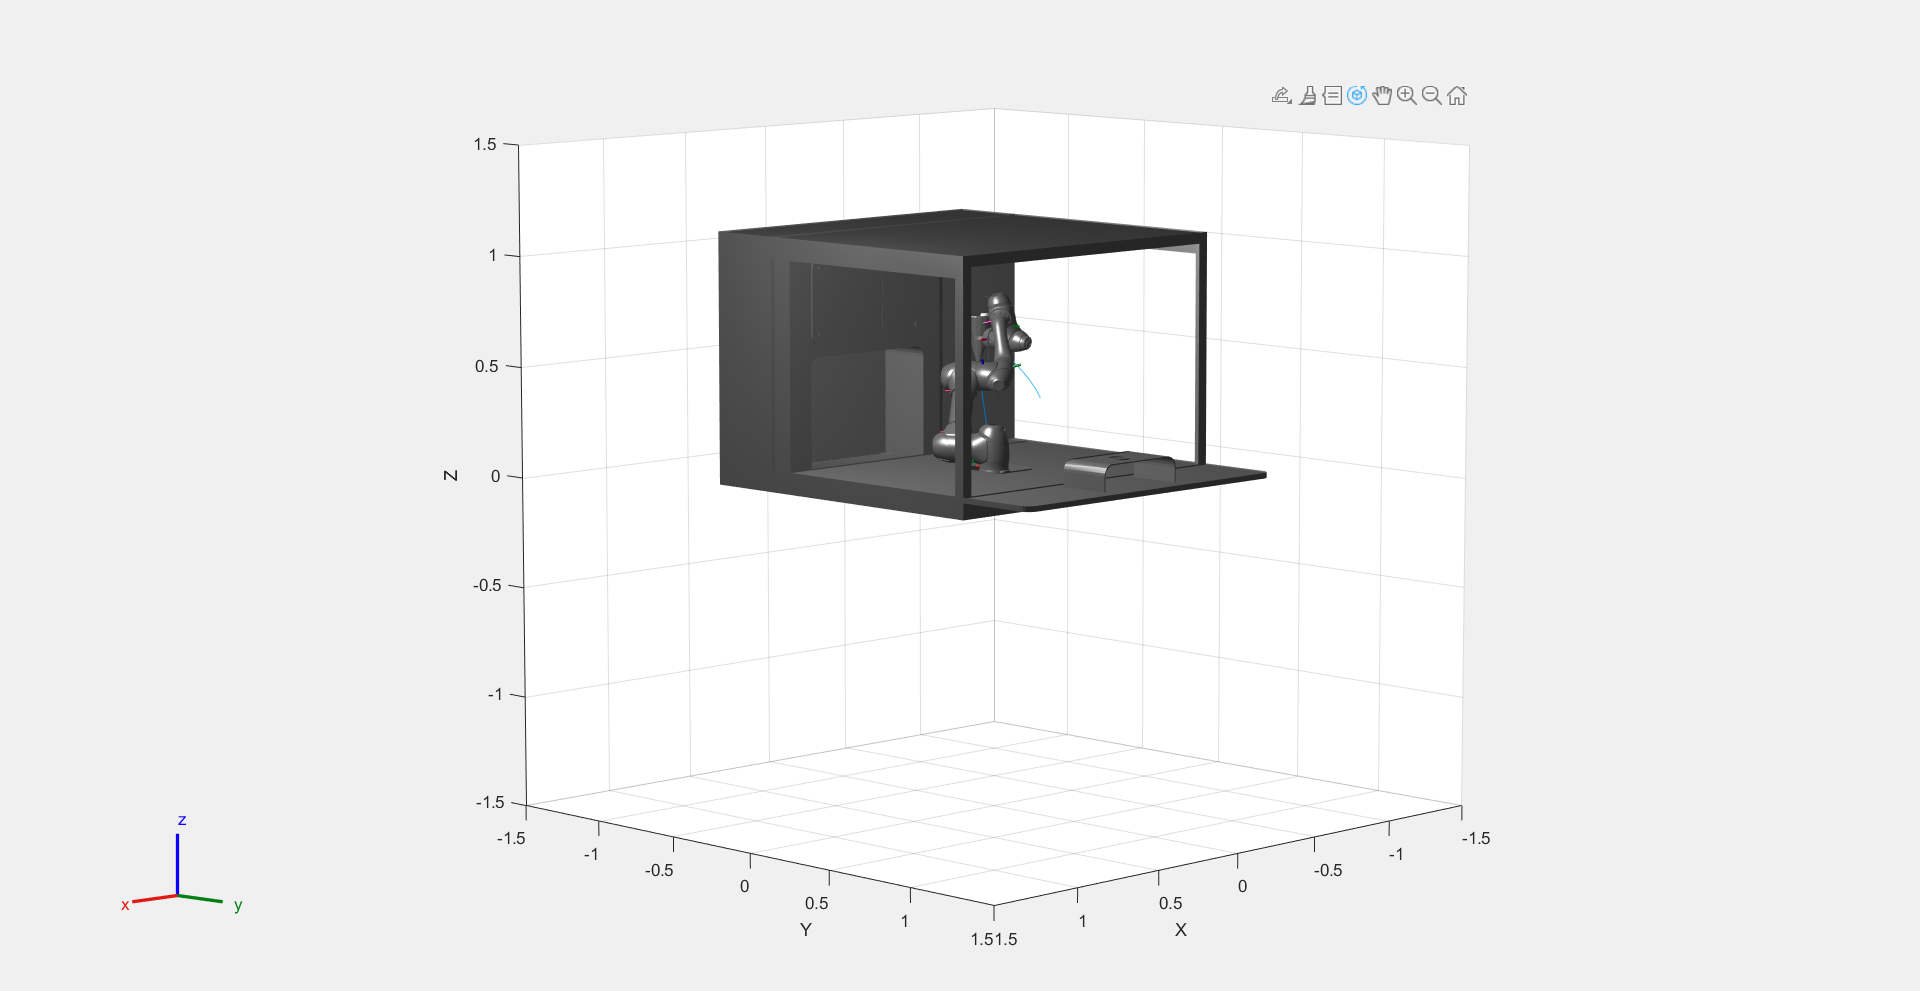

quintic_MW(OURrobot, q, hndl);

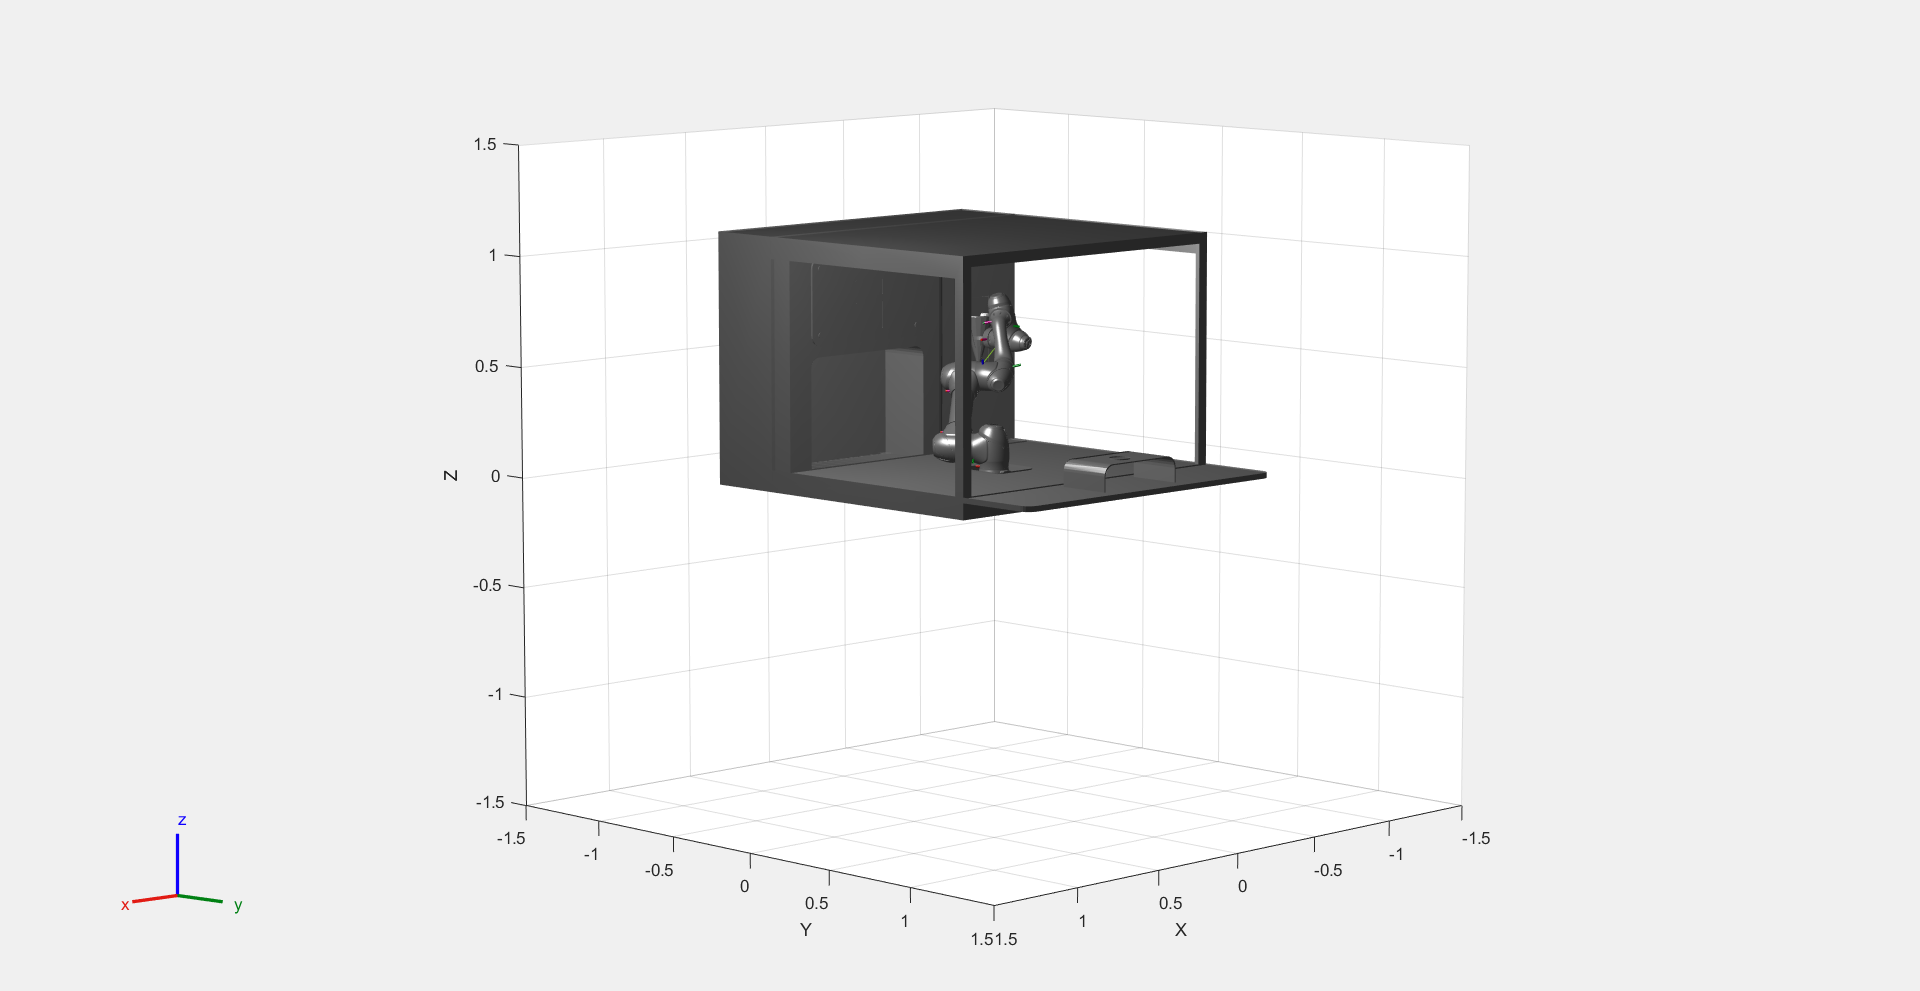


%% attacca il cono all'end effector

removeBody(OURrobot, "cono_gelato");
p = [0 -0.15 -0.15];
phi = pi/2; theta = pi/2; psi = pi/2;
R = eul2r(phi, theta, psi);
T = rot_transl(R, p);

setFixedTransform(jntcono, T);
socket.Joint = jntcono;
addBody(OURrobot, socket, "MODULE.1_FLANGE-END");
show(OURrobot, q(end,:));

## Secondo movimento

Porta il cono al cliente

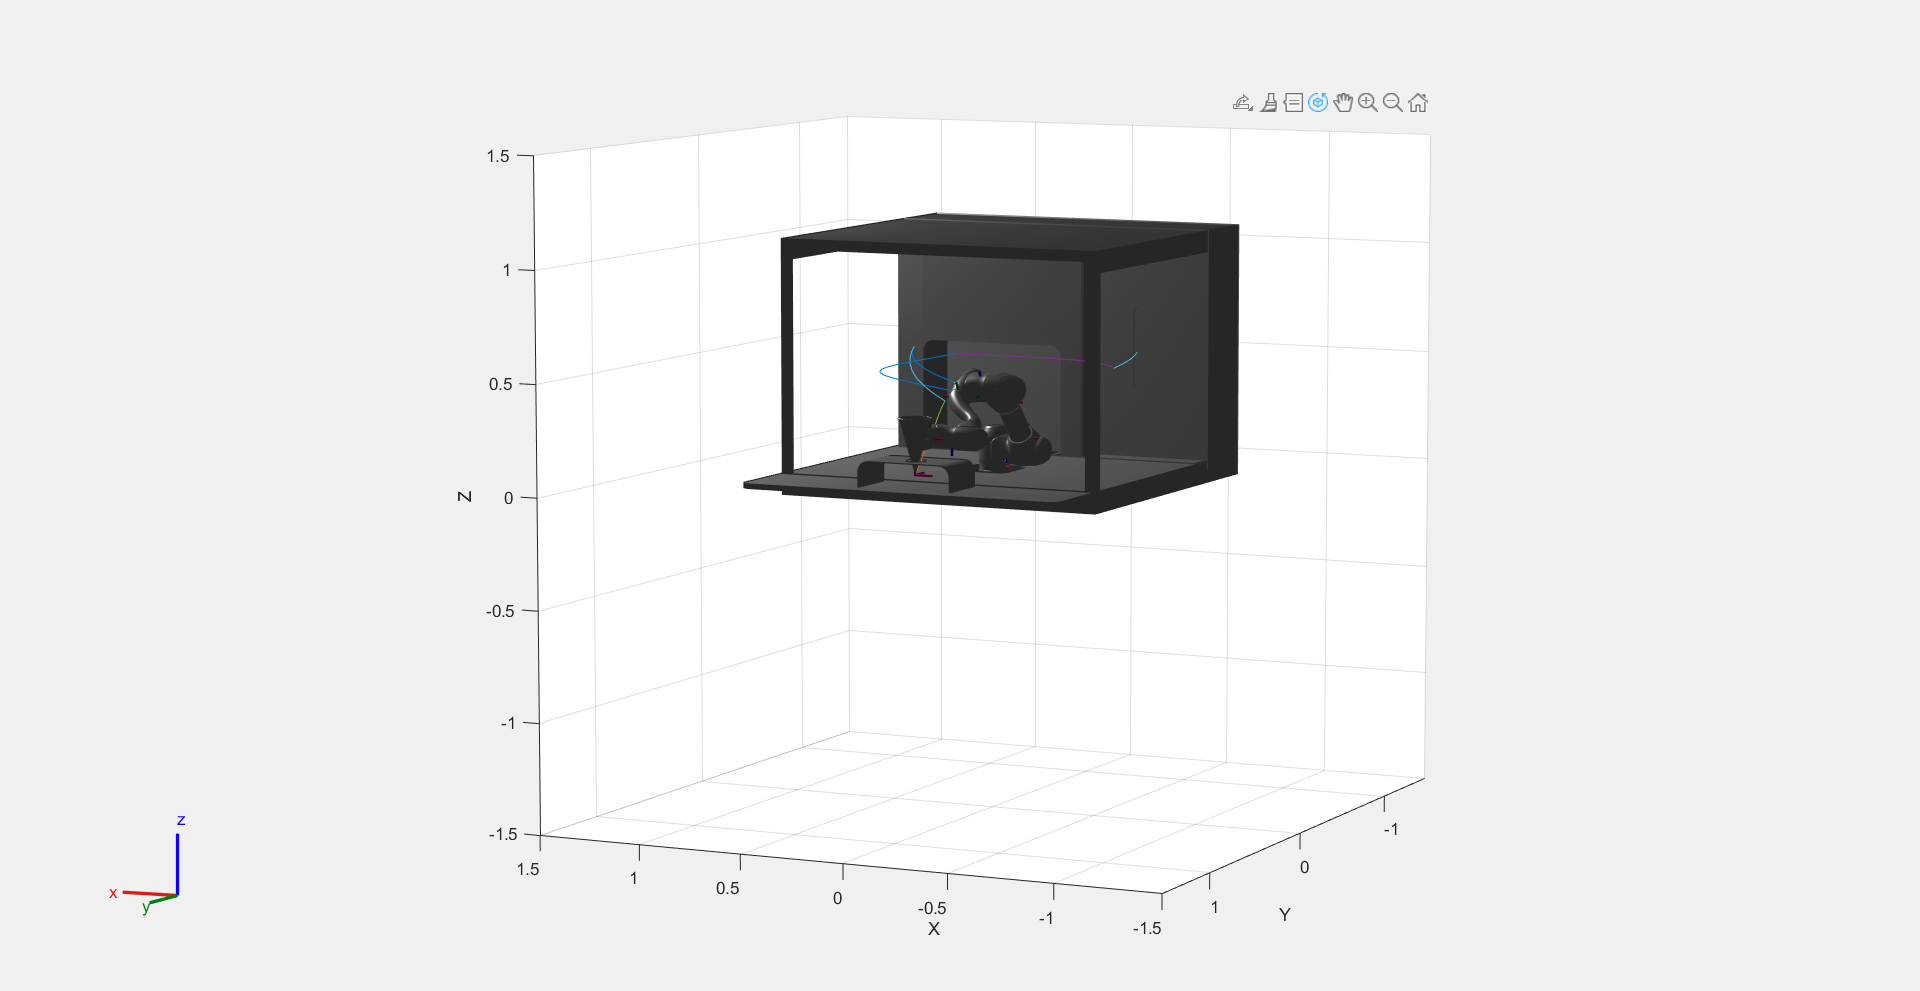


fid = fopen("gelato_principale.txt", "r");
waypoints = [];
while ~feof(fid)
    line = fgetl(fid);
    if ischar(line)
        waypoints = [waypoints; str2num(line)];
    end
end
fclose(fid);

% calcola le matrici di rototraslazione e applica la gik
posizioni = waypoints(:, 1:3);
orientazioni = waypoints(:, 4:6);

T = rot_transl_multiple(orientazioni, posizioni);

q = genInvKin_MW(T, gik, q(end, :), jointLim, poseConst);

% disegna la traiettoria e mostra l'animazione

quintic_MW(OURrobot, q, hndl);


%% deposita il cono
removeBody(OURrobot, "cono_gelato");
p = [0 0.8 0.1];
phi = 0; theta = 0; psi = 0;
R = eul2r(phi, theta, psi);
T = rot_transl(R, p);

setFixedTransform(jntcono, T);
socket.Joint = jntcono;
addBody(OURrobot, socket, "MODULE.1_Base_Giunto_Test");


## Terzo movimento

Riporta il robot alla posizione iniziale

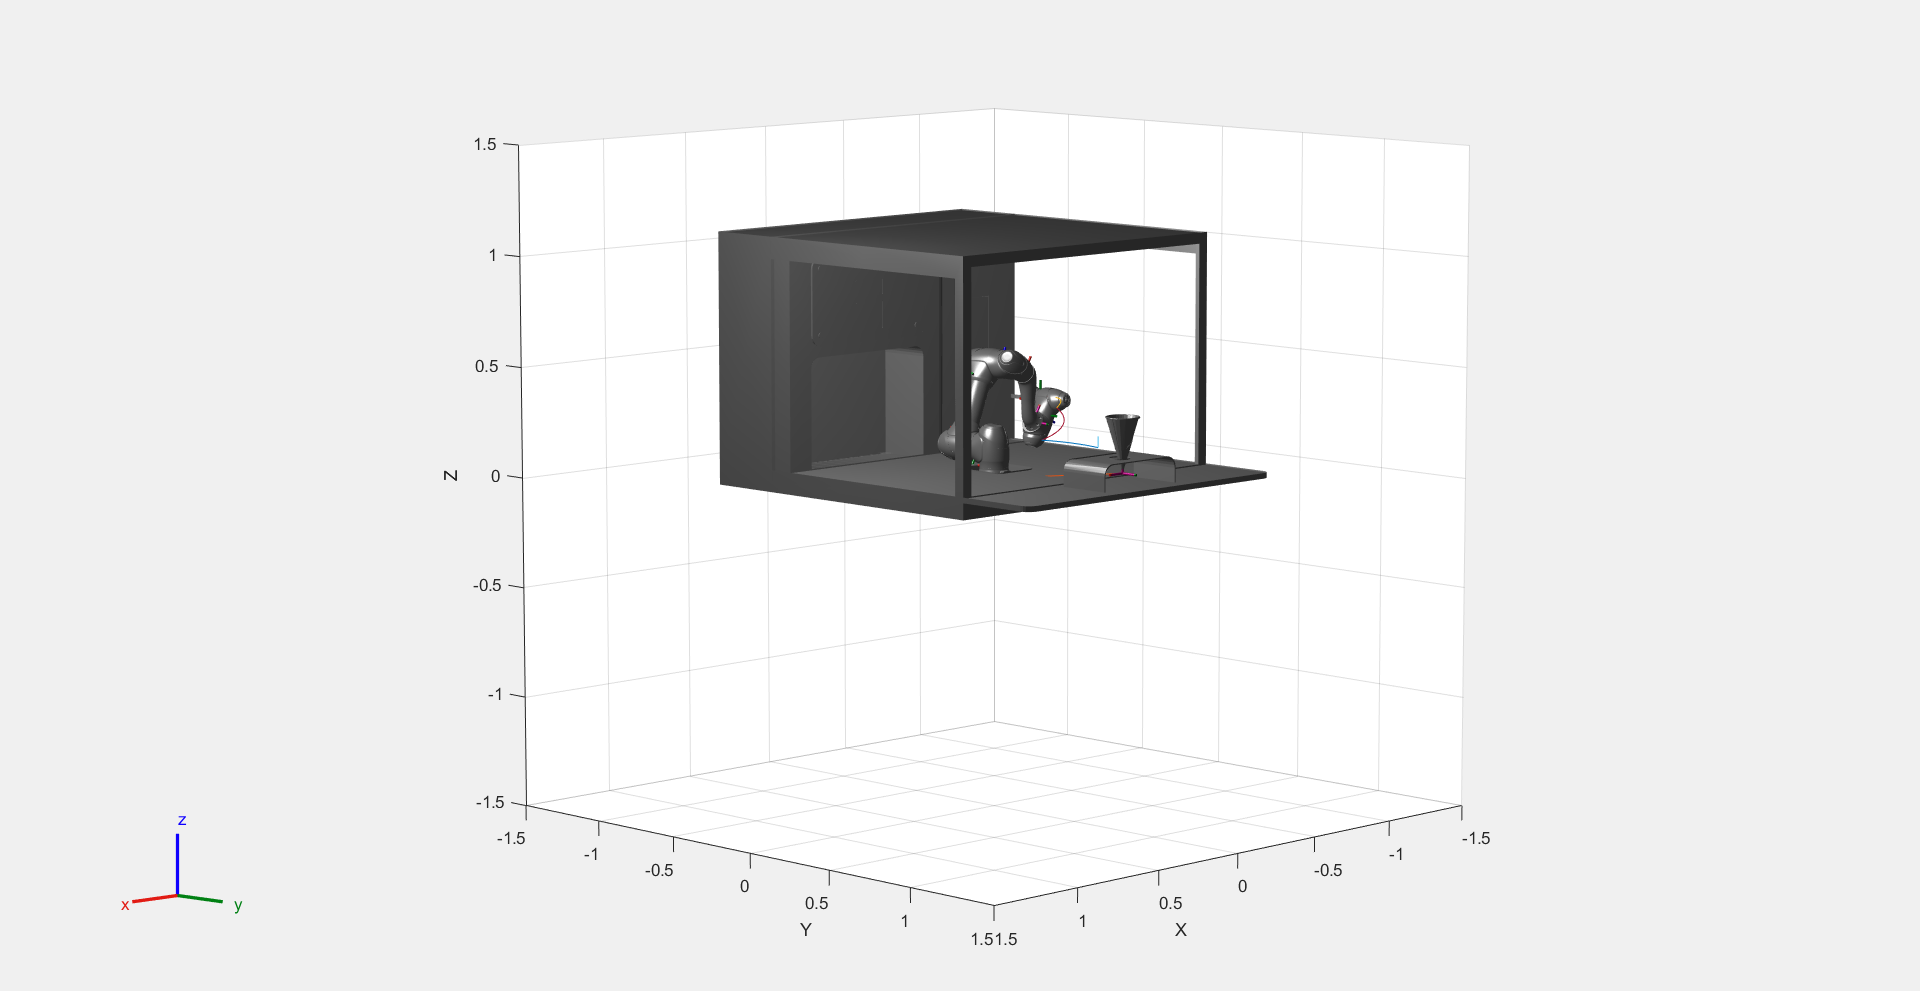


fid = fopen("gelato_reset.txt", "r");
waypoints = [];
while ~feof(fid)
    line = fgetl(fid);
    if ischar(line)
        waypoints = [waypoints; str2num(line)];
    end
end
fclose(fid);

% calcola le matrici di rototraslazione e applica la gik
posizioni = waypoints(:, 1:3);
orientazioni = waypoints(:, 4:6);

T = rot_transl_multiple(orientazioni, posizioni);

q = genInvKin_MW(T, gik, q(end, :), jointLim, poseConst);

% disegna la traiettoria e mostra l'animazione

quintic_MW(OURrobot, q, hndl);